FT=tf([0 0 25],[1 1.6 25])

FT =
 
         25
  ----------------
  s^2 + 1.6 s + 25
 
Continuous-time transfer function.



Tiempo = 0.01

Tiempo = 0.0100

Transformado=c2d(FT,Tiempo)

Transformado =
 
  0.001243 z + 0.001236
  ----------------------
  z^2 - 1.982 z + 0.9841
 
Sample time: 0.01 seconds
Discrete-time transfer function.



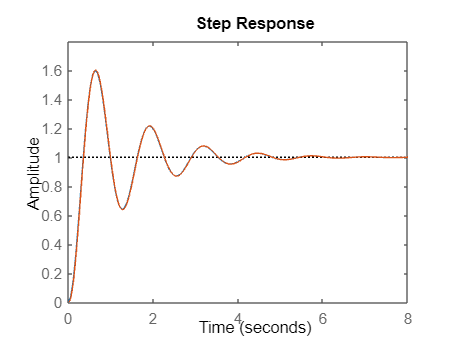

figure
hold on
step(FT)
step(Transformado)
hold off

opt=c2dOptions('Method','impulse');
Transformado=c2d(FT,Ts,opt)

Transformado =
 
    1.026 z + 3.221e-16
  -----------------------
  z^2 - 0.4607 z + 0.6597
 
Sample time: 0.26 seconds
Discrete-time transfer function.



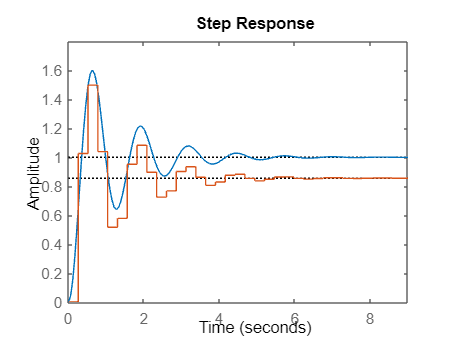

figure
hold on
step(FT)
step(Transformado)
hold off

opt=c2dOptions('Method','tustin');
Transformado=c2d(FT,Ts,opt)

Transformado =
 
  0.2591 z^2 + 0.5182 z + 0.2591
  ------------------------------
     z^2 - 0.7084 z + 0.7449
 
Sample time: 0.26 seconds
Discrete-time transfer function.



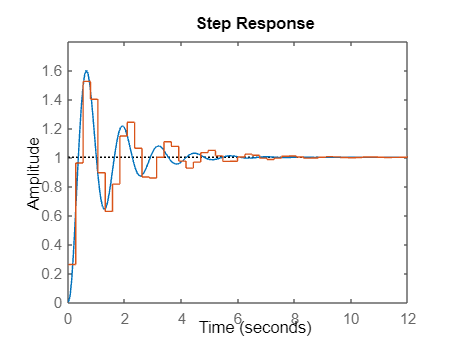

figure
hold on
step(FT)
step(Transformado)
hold off